# MECH 6323 - Final Project

Author: Jonas Wagner

Date: 2022-05-13

clc
clear
close all
sympref('MatrixWithSquareBrackets',true);
sympref('FloatingPointOutput',true);

## Intro

#### Abstract

In this project a model of dynamics of the Autonomous Vehicle (NOVA) will be examined. The NOVA team aims to eventually develop a more fundemental theory-based control strategy, yet there still exists many uncertain and changing parameters that determine the dynamics of the system. In this project a tool to analyze these dynamics, and specifically how we can look at the nonlinearities of the actuators, uncertain physical parameters, and sensor noise/malicious attack will effect the dynamics of the system.

## Nominal Plant Definition

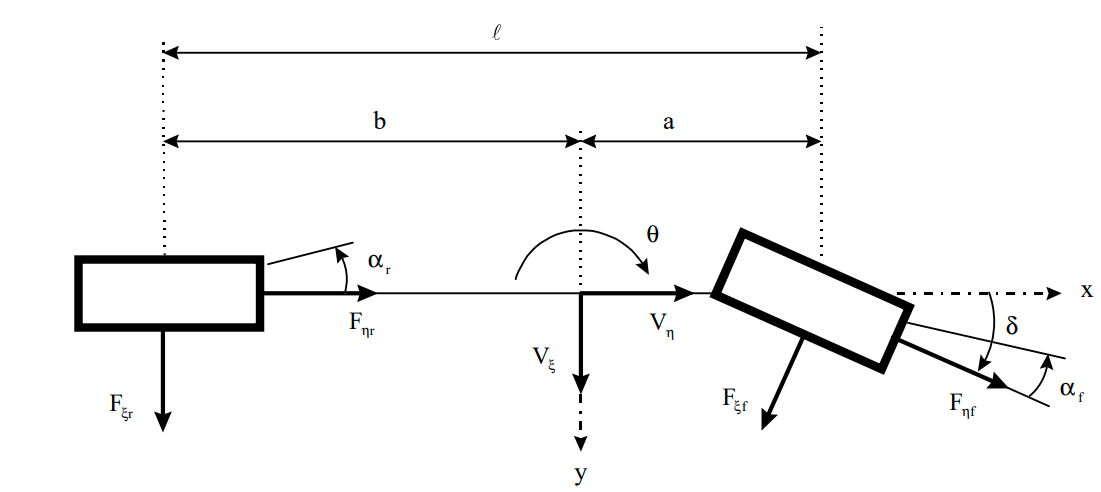

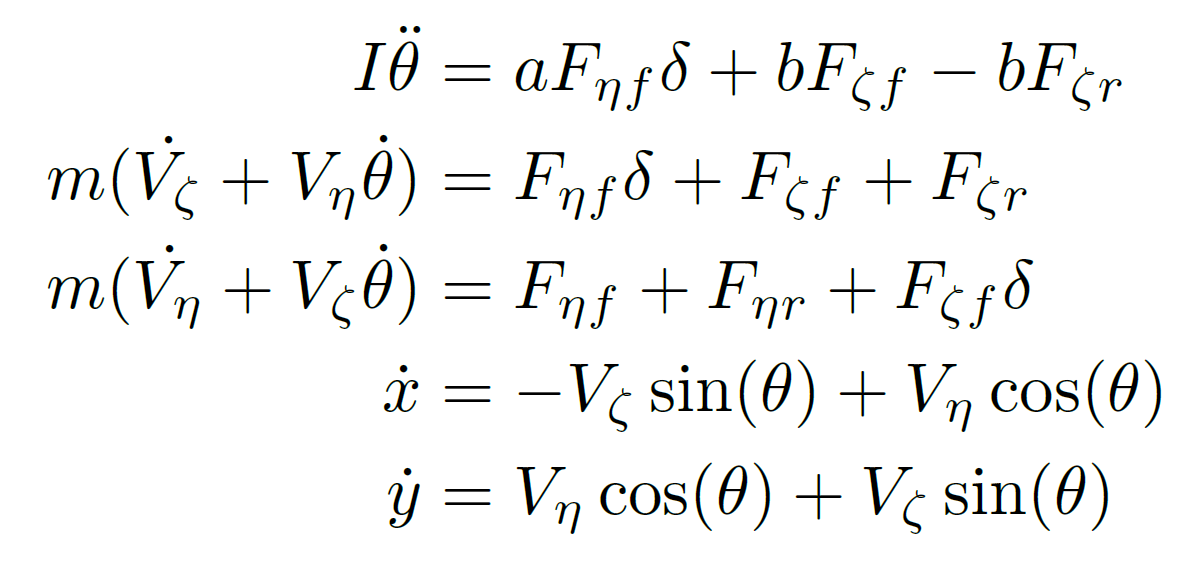    

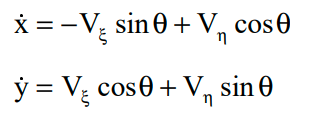

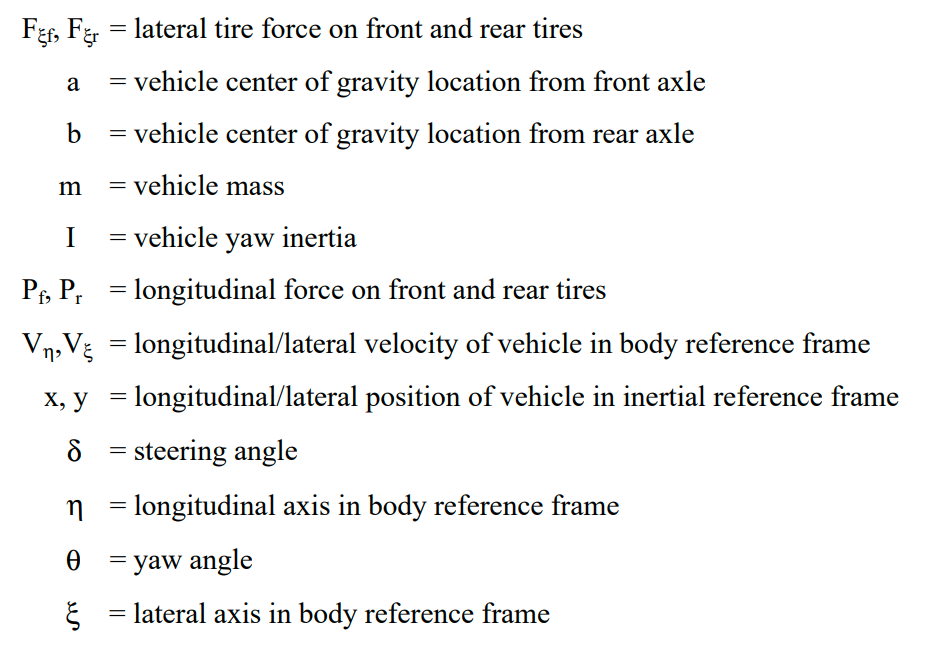


$$x = [\dot{\theta}, V_\zeta, V_\eta, x, y, \theta]^T
$$



$$u = [\delta, F_{\eta f}, F_{\eta r}, F_{\zeta f}, F_{\zeta r}]^T$$


N = 6;
x_sym = [
    sym('theta_dot')
    sym('V_zeta')
    sym('V_eta')
    sym('x')
    sym('y')
    sym('theta')
]

$$x\_sym = \left[\begin{array}{c} \dot{\theta }\\ V_{\zeta }\\ V_{\eta }\\ x\\ y\\ \theta \end{array}\right]$$

u_sym = [
    sym('delta')
    sym('F_zeta_f')
    sym('F_zeta_r')
    sym('F_eta_f')
    sym('F_eta_r')
]

$$u\_sym = \left[\begin{array}{c} \delta \\ F_{\zeta ,f}\\ F_{\zeta ,r}\\ F_{\eta ,f}\\ F_{\eta ,r} \end{array}\right]$$

params_sym = {};
params_sym.a = sym('a');
params_sym.b = sym('b');
params_sym.m = sym('m');
params_sym.I = sym('I');
params_sym.c_f = sym('c_f');
params_sym.c_r = sym('c_r');
% params_sym.alpha_f = sym('alpha_f');
% params_sym.alpha_r = sym('alpha_r');

 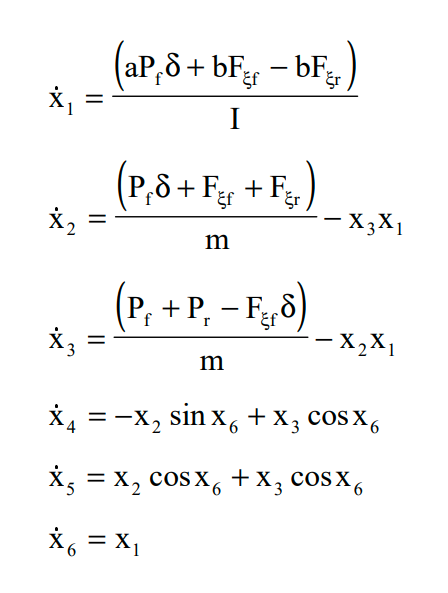       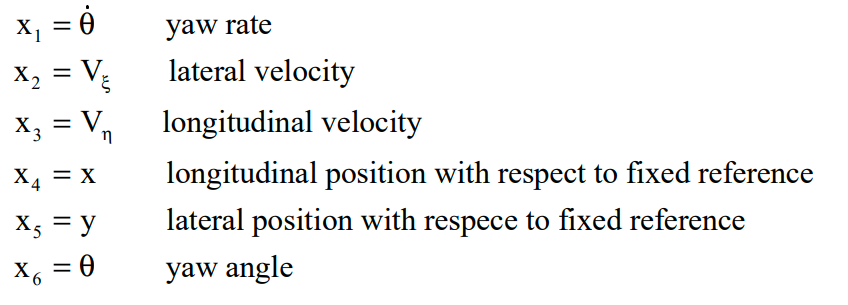

Note that $F_{\eta f} = P_f$ and $F_{\eta r} = P_r$ when in an ideal plant model... effected by slipage

bike_nonlin_dot = @(x, u, params) [
    (params.a*u(2)*u(1) + params.b*u(4) - params.b*u(5))/params.I;
    (u(2)*u(1) + u(4) + u(5))/params.m - x(3)*x(1);
    (u(2) + u(3) - u(5)*u(1))/params.m - x(2)*x(1);
    -x(2)*sin(x(6)) + x(3)*cos(x(6));
    x(2)*cos(x(6)) + x(3)*sin(x(6));
    x(1);
];
bike_nonlin_dot_sym = bike_nonlin_dot(x_sym, u_sym, params_sym)

$$bike\_nonlin\_dot\_sym = \left[\begin{array}{c} \frac{F_{\eta ,f}\,b-F_{\eta ,r}\,b+F_{\zeta ,f}\,a\,\delta }{\text{I}}\\ \frac{F_{\eta ,f}+F_{\eta ,r}+F_{\zeta ,f}\,\delta }{m}-V_{\eta }\,\dot{\theta }\\ \frac{F_{\zeta ,f}+F_{\zeta ,r}-F_{\eta ,r}\,\delta }{m}-V_{\zeta }\,\dot{\theta }\\ V_{\eta }\,\cos\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ V_{\zeta }\,\cos\left(\theta \right)+V_{\eta }\,\sin\left(\theta \right)\\ \dot{\theta } \end{array}\right]$$

eq_bike_latex = ['$\dot{x} = ', latex(bike_nonlin_dot_sym),'$'];

#### Nominal Model

params.a = 1.228;
params.b = 1.5618;
params.m = 1500;
params.I = 12;
params.c_f = 0.12;
params.c_r = 0.16;


% params.m = params.m * 10;
% params.I = params.I * 100;

bike_nonlin_dot_nom = bike_nonlin_dot(x_sym, u_sym, params)

$$bike\_nonlin\_dot\_nom = \left[\begin{array}{c} 0.1302\,F_{\eta ,f}-0.1302\,F_{\eta ,r}+0.1023\,F_{\zeta ,f}\,\delta \\ 6.6667e-04\,F_{\eta ,f}+6.6667e-04\,F_{\eta ,r}+6.6667e-04\,F_{\zeta ,f}\,\delta -V_{\eta }\,\dot{\theta }\\ 6.6667e-04\,F_{\zeta ,f}+6.6667e-04\,F_{\zeta ,r}-6.6667e-04\,F_{\eta ,r}\,\delta -V_{\zeta }\,\dot{\theta }\\ V_{\eta }\,\cos\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ V_{\zeta }\,\cos\left(\theta \right)+V_{\eta }\,\sin\left(\theta \right)\\ \dot{\theta } \end{array}\right]$$

## Linearized Model

This is an unrealistic thing to do outside of single time-steps

A_sym = jacobian(bike_nonlin_dot(x_sym,u_sym,params_sym),x_sym)

$$A\_sym = \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ -V_{\eta } & 0 & -\dot{\theta } & 0 & 0 & 0\\ -V_{\zeta } & -\dot{\theta } & 0 & 0 & 0 & 0\\ 0 & -\sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0 & -V_{\zeta }\,\cos\left(\theta \right)-V_{\eta }\,\sin\left(\theta \right)\\ 0 & \cos\left(\theta \right) & \sin\left(\theta \right) & 0 & 0 & V_{\eta }\,\cos\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

B_sym = jacobian(bike_nonlin_dot(x_sym,u_sym,params_sym),u_sym)

$$B\_sym = \left[\begin{array}{ccccc} \frac{F_{\zeta ,f}\,a}{\text{I}} & \frac{a\,\delta }{\text{I}} & 0 & \frac{b}{\text{I}} & -\frac{b}{\text{I}}\\ \frac{F_{\zeta ,f}}{m} & \frac{\delta }{m} & 0 & \frac{1}{m} & \frac{1}{m}\\ -\frac{F_{\eta ,r}}{m} & \frac{1}{m} & \frac{1}{m} & 0 & -\frac{\delta }{m}\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

A = matlabFunction(A_sym, 'Vars', {x_sym, u_sym, sym('a'), sym('b'), sym('m'), sym('I')});
B = matlabFunction(B_sym, 'Vars', {x_sym, u_sym, sym('a'), sym('b'), sym('m'), sym('I')});

## Uncertain Plant Dynamics and Disturbances

All the calculations here are dependent on the nominal dynamics.

params

params = struct with fields:
      a: 1.2280
      b: 1.5618
      m: 1500
      I: 12
    c_f: 0.1200
    c_r: 0.1600


### Physical Disturbances

#### Tire Slipage

We have options to model the tire slipage better (actually what alphas are used for) but they are highly nonlinear and are also highly dependent on  so it is very difficult to model acurately. Instead we will model tire with a disturbance input and have it be modeled a disturbance within the  for each tire. For simplicity we will make it a parameter that is really only dependent on the unchanging parameters since these are what effect this in real life.

% W_zeta_f = 1e-3 * (params.a / params.b) / params.m
% W_zeta_r = 1e-3 * (params.b / params.a) / params.m

Actually... since idk what I am actually talking about for vehicle dynamics, we can going to refer back to what Adi had done for the optimization and use the less specific (just that it is not derived from the parameters directly, but is instead determined experimentally) that is tuned per the vehicle operation at the specific weight/configuration/etc.

#### Wind Resistance

Although the NOVA vehcile will be going slow enough that wind resistance is negligable, including it seemed worth while. The effect of wind resistance itself is modeled as two components. 

First, the force due to movement through air proportional to speed is added in the system directly opisite the currect direction of movement. This is inacurrate in general due to car body shape but this could also be modified to be different weighting from different directions but we will instead just provide for this parameter to vary greatly. 


$$F_{\eta,w} = k_{\eta,w} \cdot V_{\eta}$$



$$F_{\zeta,w} = k_{\zeta,w} \cdot V_{\zeta}$$


Secound an additive noise of general stead-state wind either fights against or assists the vehicle. Since wind direction generally changes slowly we will only be looking at lower frequencies.


$$F_{ws} = W_{ws} \cdot z_{ws} \cdot (cos(\theta - \theta_{ws}) \hat{u}_{\eta} + sin(\theta - \theta_{ws}) \hat{u}_{\zeta}), \ z_{ws} \in [0,1], \ \theta_{ws} \in [0, 2pi]$$



$$\theta_{ws} = W_{w,\theta_{ws}} z_{w,\theta_{ws}}$$


k_ws = 10;
tau_ws = 100;
W_ws = zpk([],-1/tau_ws,-k_ws/tau_ws)

W_ws =
 
    -0.1
  --------
  (s+0.01)
 
Continuous-time zero/pole/gain model.



W_ws_theta = zpk([], -1/tau_ws, 2*pi/tau_ws)

W_ws_theta =
 
  0.062832
  --------
  (s+0.01)
 
Continuous-time zero/pole/gain model.



both a multiplicative noise on the standard are resistance of dependent on the vehicle velocity.

Currently this is not implimented in the simulation fully. Instead the following more simplistic method is used:


$$F_{\eta,r} = - k_{ws,\eta} * V_\eta$$


W_ws = - k_ws;

Since wind resistance is an over complication we are eliminating it for this time.

W_ws = 0;

### Uncertain/Nonlinear Actuators

#### Steering and Forward Force Delays

Both a human and autonomous driver takes a while to react, while both the steering mechanism and engine/drivetrain also contain delays. We also assume it is only a front-wheel drive vehicle, so only the front wheel will be providing force to move the vehicle.


$$\delta = W_{driver} \cdot u_\delta$$


k_driver = 1;
tau_driver = 0.1;
% tau_driver = 1e-2;
W_driver = zpk([],-1/tau_driver,k_driver/tau_driver)

W_driver =
 
    10
  ------
  (s+10)
 
Continuous-time zero/pole/gain model.



W_driver = k_driver;


$$F_{eta,f} = W_{drivetrain} \cdot W_{driver} \cdot u_{gas}$$


k_drivetrain = 10;
tau_drivetrain = 2;
% tau_drivetrain = 1e-2;
W_drivetrain = zpk([],-1/tau_drivetrain,k_drivetrain/tau_drivetrain)

W_drivetrain =
 
     5
  -------
  (s+0.5)
 
Continuous-time zero/pole/gain model.



W_drivetrain = k_drivetrain;

#### Slip angle effects

The front slip angle is calculated as:


$$\alpha_f = \delta - \frac{a \dot{\theta} + V_\zeta}{V_\eta}$$


and the rear slip angle is 


$$\alpha_r = \frac{b \dot{\theta} - V_\zeta}{V_\eta}$$


Then we have (ignoring saturation regions... remaining linear for this analysis)


$$F_{\zeta,f} = c_f \alpha_f$$


and


$$F_{\zeta,r} = c_r \alpha_r$$


where $c_f$ and $c_r$ are the cornering stifnesses uncertain parameters.

### Sensors and Measurement Noise

#### Gyroscope

The gyroscope will measure the rotational velocity of the system which will allow an observer to measure the current state with fairly high acuracy if you average it (which isn't really that useful when you would need to integrate or differentiate them) but will be noisy at higher frequencies if sampled often.

The gyro measurment output will therefore be:


$$y_{gyro} = \dot{\theta} + W_{gyro} \cdot z_{gyro}, \ z_{gyro} \in [-1,1]$$


z_0_gyro = 0.0001;
tau_gyro = 0.001;
bw_gyro = 500;
W_gyro = zpk(-1/tau_gyro / bw_gyro, -1/tau_gyro * bw_gyro, z_0_gyro)

W_gyro =
 
  0.0001 (s+2)
  ------------
    (s+5e05)
 
Continuous-time zero/pole/gain model.



#### Spedometer

The spedometer is just a measurement directly of the Longitudinal Velocity, $V_\eta$, and will have a measurement noise that is only really aparent at higher frequencies.

The gyro measurment output will therefore be:


$$y_{sped} = V_{\eta}  + W_{sped} \cdot z_{sped}, \ z_{sped} \in [-1,1]$$


z_0_sped = 0.1;
tau_sped = 0.01;
bw_sped = 10;
W_sped = zpk(1/tau_sped / bw_sped, 1/tau_sped * bw_sped, z_0_sped)

W_sped =
 
  0.1 (s-10)
  ----------
   (s-1000)
 
Continuous-time zero/pole/gain model.



#### GPS

The GPS system will be used to calculate the global position over a longer period of time for the system. Similar to the Gyroscope, the GPS will have error at low ends and isn't going to ever truely be acurate over-time in a real-world situation by itself without other information used by a Kalmen Filter or similar in congunction with other sensors (such as Lidar) and orther localization techniques (which is a big part of what NOVA has been working on this semester). We will assume that the sensor error output from the gps will be white noise that is filtered out mostly (becouse of the way it is averaged and sampled so higher frequencies become less important) except for a region.


$$y_{gps, x} = x  + W_{gps} \cdot z_{gps}, \ z_{gps} \in [-1,1]$$



$$y_{gps, y} = y + W_{gps} \cdot z_{gps}, \ z_{gps} \in [-1,1]$$


z_0_gps = 0.1;
tau_gps = 0.1;
bw_gps  = 10;
W_gps = z_0_gps .* tf(bw_gps/tau_gps, [1 bw_gps/tau_gps (1/tau_gps)^2])

W_gps =
 
         10
  -----------------
  s^2 + 100 s + 100
 
Continuous-time transfer function.



### Eyeballs (Vison & Loclaization)

The big thing that isn't included in this entire thing is the actual vision that the vehicle has. Generally this is almost a cheat catch-all of everything since although the sensors will have higher accuracy and ultimently a faster response time, it is the vision that will make things consistant. Similarly to the 'driver-delay', we will have a sensing type delay, but all of the information we are able to be awar of is available (although we will have considerably more noise.


$$y_{vision} = y + W_{vision} \cdot z_{vision} , \ z_{vision} \in [-1,1]$$


z_0_vision = [
    0.1;
    3;
    3;
    5;
    5;
    pi/20
];
tau_vision = 0.1;
bw_vision = 10;
W_vision = tf(bw_vision/tau_vision, [1 bw_vision/tau_vision (1/tau_vision)^2]);
W_vision = diag(z_0_vision) * W_vision;




%%%%%
W_vision = eye(size(z_0_vision,1));

### Parameteric Uncertainty

Parameteric Uncertainty essentially just assumes deviations from potential modeling issues. For the current analysis this is ignored in order to focus on actuator uncertainty.

Actually, I ended up deciding to do just that... but just with a more standard thing.

params_nom = params;
params_u = params;
a_u = ureal('a', params.a, 'Percentage', 1);
b_u = ureal('b', params.b, 'Percentage', 1);
m_u = ureal('m', params.m, 'Percentage', 1);%25);
I_u = ureal('I', params.I, 'Percentage', 1);%25);
params_u.a = a_u;
params_u.b = b_u;
params_u.m = m_u;
params_u.I = I_u;
params_u.c_f = ureal('c_f', params.c_f, 'Percentage', 1);%2);
params_u.c_r = ureal('c_r', params.c_r, 'Percentage', 1);%2);


## Plant Model and Controller Design

#### Nominal Plant

A_nom = @(x_0, u_0) A(x_0, u_0, params.a, params.b, params.m, params.I);
B_nom = @(x_0, u_0) B(x_0, u_0, params.a, params.b, params.m, params.I);

V_eta_0 = 10;

x_eq = [0; 0; V_eta_0; 0; 0; pi/4];
x_0 = [-0.1; 0.1; 1.1*V_eta_0; 0; 0; pi/4+0.001];
x_0 = x_eq

x_0 =          0
         0
   10.0000
         0
         0
    0.7854


u_0 = ones(5,1);
r_0 = [0; 0; V_eta_0; 0; 0; pi/4];
% % R = @(t) r_0 + r_0(2)/sqrt(2) * [0;0;0;t;t;0];
sys_nom = ss(A_nom(x_0,u_0), B_nom(x_0,u_0), eye(N), 0)

sys_nom =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1        0        0        0        0        0        0
   x2      -10        0        0        0        0        0
   x3        0        0        0        0        0        0
   x4        0  -0.7071   0.7071        0        0   -7.071
   x5        0   0.7071   0.7071        0        0    7.071
   x6        1        0        0        0        0        0
 
  B = 
               u1          u2          u3          u4          u5
   x1      0.1023      0.1023           0      0.1302     -0.1302
   x2   0.0006667   0.0006667           0   0.0006667   0.0006667
   x3  -0.0006667   0.0006667   0.0006667           0  -0.0006667
   x4           0           0           0           0           0
   x5           0           0           0           0           0
   x6           0           0           0           0           0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0

% Reference Signal
R_fun = @(t) (r_0 + [0;0;0;1;0;0]*r_0(2)*t*cos(r_0(6)) + [0;0;0;0;1;0]*r_0(3)*t*sin(r_0(6)));
% just a test... do it below based on function...
t = 0:0.01:1001;
time = t;
data = cell2mat(arrayfun(R_fun,time, 'UniformOutput', false));
R = timeseries(data,time,'Name', 'r');


#### Uncertain Plant

A_u = [
    0, 0, 0, 0, 0, 0; 
    -x_0(3), 0, -x_0(1), 0, 0, 0; 
    -x_0(2), -x_0(1), 0, 0, 0, 0; 
    0, -sin(x_0(6)), cos(x_0(6)), 0, 0, - x_0(2)*cos(x_0(6)) - x_0(3)*sin(x_0(6)); 
    0, cos(x_0(6)), cos(x_0(6)), 0, 0, - x_0(3)*sin(x_0(6)) - x_0(2)*sin(x_0(6)); 
    1, 0, 0, 0, 0, 0
];
B_u = [
    (u_0(2)*a_u)/I_u, (a_u*u_0(1))/I_u, 0, b_u/I_u, -b_u/I_u; 
    x_0(1)/m_u, u_0(1)/m_u, 0, 1/m_u, 1/m_u; 
    -x_0(5)/m_u, 1/m_u, 1/m_u, 0, -u_0(1)/m_u; 
    0, 0, 0, 0, 0; 
    0, 0, 0, 0, 0; 
    0, 0, 0, 0, 0
];
C_u = eye(size(A_u));%[diag([1, 1, 0, 1, 1]),zeros(5,1)];%
D_u = zeros(size(C_u,1),size(B_u,2));
sys_plant_u = uss(A_u,B_u,C_u,D_u);

The uncertain plant with all the dynamics is actually really complicated and not only is dependent on the changing parameters and nonlinearities due to actuators; but is also really complicated with conections to the global coordnate system. We therefore can develop a local plant that incorporates less nonlinearities while being tracked seperatly in the global reference frame. The controller that works for this would not need to worry about that particular nonlinearity.

sys_plant_u_local = uss(A_u([1:3,6],[1:3,6]),B_u([1:3,6],1:5),eye(4),zeros(4,5))

sys_plant_u_local =

  Uncertain continuous-time state-space model with 4 outputs, 5 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    I: Uncertain real, nominal = 12, variability = [-1,1]%, 2 occurrences
    a: Uncertain real, nominal = 1.23, variability = [-1,1]%, 1 occurrences
    b: Uncertain real, nominal = 1.56, variability = [-1,1]%, 1 occurrences
    m: Uncertain real, nominal = 1.5e+03, variability = [-1,1]%, 2 occurrences

Type "sys_plant_u_local.NominalValue" to see the nominal value, "get(sys_plant_u_local)" to see all properties, and "sys_plant_u_local.Uncertainty" to interact with the uncertain elements.



## Simulink Modeling

### Plant Modeling

(see the end for the simulink model printouts)

#### Generalized Linear Plant Model:

params = params_u;
% mdl = 'sim_hinf_bike';
% W_driver = 1;
W_sped = 0;
% W_gps = 0;
W_gyro = 0;
% W_vision = eye(6);
mdl = 'fast_test';
% open(mdl)
sys_plant = find_sys_plant(mdl)

sys_plant =

  Uncertain continuous-time state-space model with 22 outputs, 9 inputs, 8 states.
  The model uncertainty consists of the following blocks:
    I: Uncertain real, nominal = 12, variability = [-1,1]%, 2 occurrences
    a: Uncertain real, nominal = 1.23, variability = [-1,1]%, 1 occurrences
    b: Uncertain real, nominal = 1.56, variability = [-1,1]%, 1 occurrences
    m: Uncertain real, nominal = 1.5e+03, variability = [-1,1]%, 2 occurrences

Type "sys_plant.NominalValue" to see the nominal value, "get(sys_plant)" to see all properties, and "sys_plant.Uncertainty" to interact with the uncertain elements.



% if  false
%     sys_plant.NominalValue
% end

## H-infty Controller Design

The rank of our controllability is needed to ensure that the system is actually controllable.

ctr_mat = ctrb(sys_plant);
ctrb_rank = rank(ctr_mat)

ctrb_rank = 3

`In many different equalibrium cases the rank of controllability is 1. In other words, the system had many uncontrollable modes that lead to a complete failure to even have a controllable (let alone robust) system. This is what prompted the change to instead allow for the driver to have direct control of the inputs into the system. This doesn't make sense in reality, however it does `

% hinfsyn
nmeas = 16;
ncont = 5;
K_hinf = calc_K_hinf(mdl,nmeas,ncont);

State-space model with 5 outputs, 16 inputs, and 8 states.


info =   hinfINFO with properties:

    gamma: 2.4740
        X: [8×8 double]
        Y: [8×8 double]
       Ku: [5×8 double]
       Kw: [20×8 double]
       Lx: [8×16 double]
       Lu: [5×16 double]
     Preg: [27×25 ss]
       AS: [21×21 ss]


A controller was able to be developed, for some very specificic linearizations,

## Uncertain Plant Analysis

L = K_hinf * sys_plant((-nmeas:-1) + size(sys_plant,1), 1:ncont)

L =

  Uncertain continuous-time state-space model with 5 outputs, 5 inputs, 16 states.
  The model uncertainty consists of the following blocks:
    I: Uncertain real, nominal = 12, variability = [-1,1]%, 1 occurrences
    a: Uncertain real, nominal = 1.23, variability = [-1,1]%, 1 occurrences
    b: Uncertain real, nominal = 1.56, variability = [-1,1]%, 1 occurrences

Type "L.NominalValue" to see the nominal value, "get(L)" to see all properties, and "L.Uncertainty" to interact with the uncertain elements.



It is worth noting that the controller, even in the open loop configuration, was able to eliminate dependence on both $m$ and $c_f$.

diskmargin(L)

ans = 5×1 struct array with fields:
    GainMargin
    PhaseMargin
    DiskMargin
    LowerBound
    UpperBound
    Frequency
    WorstPerturbation


This result shows us that the system is robust at all 

## Testing Controller

The contntroller can be 

t_end = 250;
simout = sim(mdl,'SimulationMode','normal',...
            'StartTime', '0', 'StopTime', num2str(t_end),...
            'SaveState','on','StateSaveName','xout',...
            'SaveOutput','on','OutputSaveName','yout',...
            'SaveFormat', 'Dataset');

## Ploting Things

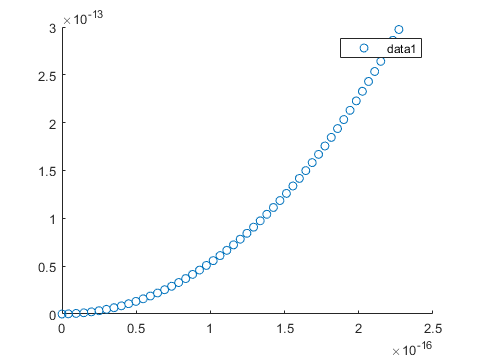

t_out = simout.tout;

e_signal = simout.yout{1}.Values;
r_signal = simout.yout{2}.Values;
y_vision_signal = simout.yout{7}.Values;

x_signal = simout.xout{3}.Values.Data;%simout.xout{3}.Values.Data;

x_global = y_vision_signal.Data(:,4:5);

figure
% scatter(x_signal(:,4),x_signal(:,5))
% scatter(x_signal(:,4),x_signal(:,5))
scatter(x_global(:,1),x_global(:,2))
legend

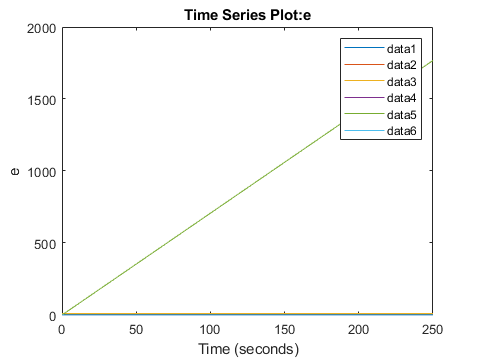




figure
plot(e_signal)
legend()

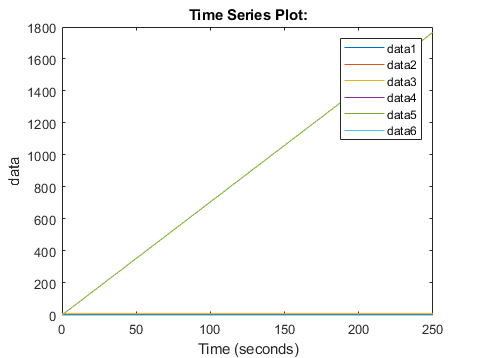

% legend({'theta dot ','V_x', 'V_y'})
figure
plot(r_signal)
legend

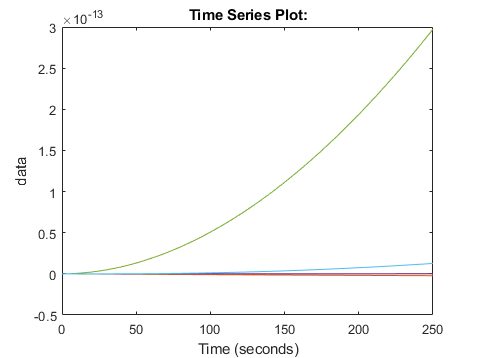

figure
plot(y_vision_signal)

## Print outs

runPrints = false;
if runPrints

#### Plant Internal Diagram

The plant internal diagram includes the orignal physical dynamics within a standard LTI system block and all of the weighting functions for the actuators and sensors containing the uncertainty.

plant_fname = 'plant_bike_lin';
open(plant_fname)
imgname = ['plant_w_act_&_sen', '.png'];
print(['-s', plant_fname,'/Plant'], '-dpng', imgname)
imshow(imgname)

#### plant_bike_lin.slx

The plant is then agrigated within another subsystem block that is structured as a generalized plant model to be used for designing the -controller. 

plant_fname = 'plant_bike_lin';
imgname = [plant_fname, '.png'];
print(['-s', plant_fname], '-dpng', imgname)
imshow(imgname)

#### fast_test.slx

Becouse of many issues with the complicated model, a simpler system that implimented a less restrictive actuator system (and ignores the wind disturbances which made stabilization nearly impossible) a simpler model (shown below) was created instead.

plant_fname = 'fast_test';
open(plant_fname)
imgname = [plant_fname, '.png'];
print(['-s', plant_fname], '-dpng', imgname)
imshow(imgname)
% imshow(['plant_w_act_&_sen', '.png'])
% imshow(['plant_bike_lin', '.png'])
% imshow(['fast_test', '.png'])
% Print Out as pdf
% fname = matlab.desktop.editor.getActiveFilename;
% export(fname, [fname(1:length(fname)-4),'.pdf']); 
%saves the .mlx file to a .pdf in the same directory with the same name
end

function sys_plant = find_sys_plant(mdl)
    % comment out controller
    set_param([mdl,'/Controller'],'Commented','on');
%     do io things
    clear io
%     io(1) = linio([mdl,'/w_r'],1,'input');
%     io(2) = linio([mdl,'/w'],1,'input');
%     io(3) = linio([mdl,'/u'],1,'openinput');
%     io(4) = linio([mdl,'/Plant'],1,'output');
%     io(5) = linio([mdl,'/Plant'],2,'output');
%     io(6) = linio([mdl,'/Plant'],3,'output');

    io(1) = linio([mdl,'/r'],1,'input');
    io(2) = linio([mdl,'/z_gyro'],1,'input');
    io(3) = linio([mdl,'/z_gps'],1,'input');
    io(4) = linio([mdl,'/z_sped'],1,'input');
    io(5) = linio([mdl,'/K_u_gain'],1,'input');
    io(6) = linio([mdl,'/e_sum'],1,'output');
    io(7) = linio([mdl,'/r_gain_out'],1,'output');
    io(8) = linio([mdl,'/gps_y_sum'],1,'output');
    io(9) = linio([mdl,'/gps_x_sum'],1,'output');
    io(10) = linio([mdl,'/gyro_sum'],1,'output');
    io(11) = linio([mdl,'/sped_sum'],1,'output');
    io(12) = linio([mdl,'/vision'],1,'output');

    sys_plant = ulinearize(mdl,io);
%     uncomment controller
    set_param([mdl,'/Controller'],'Commented','off');

%     [A,B,C,D] = linmod(mdl);
%     sys_plant = ss(A,B,C,D)

end

function K_hinf = calc_K_hinf(mdl, nmeas, ncont)
    sys_plant = find_sys_plant(mdl);
    [K_hinf,~,~,info] = hinfsyn(sys_plant,nmeas,ncont);
    size(K_hinf)
    info
end